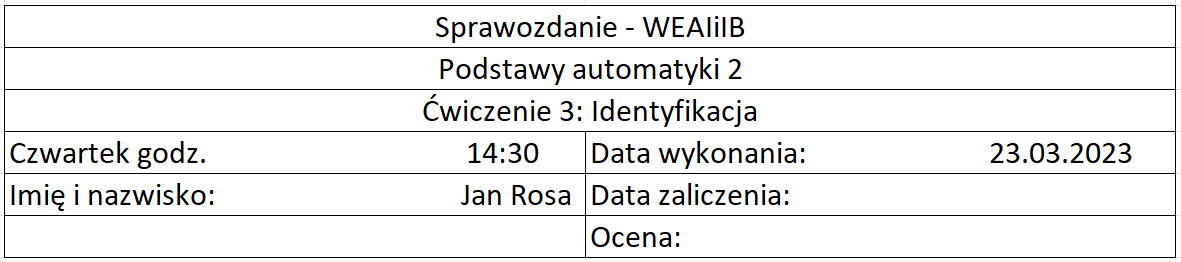

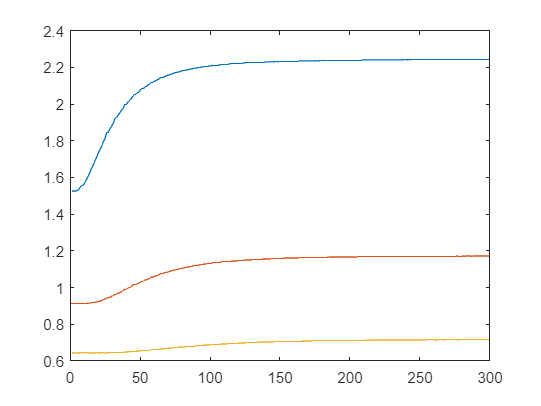

load pomiary_3out.mat
plot(pomiary_3out)

obiektA21 =
 
               0.7179
  exp(-7*s) * --------
              30 s + 1
 
Continuous-time transfer function.



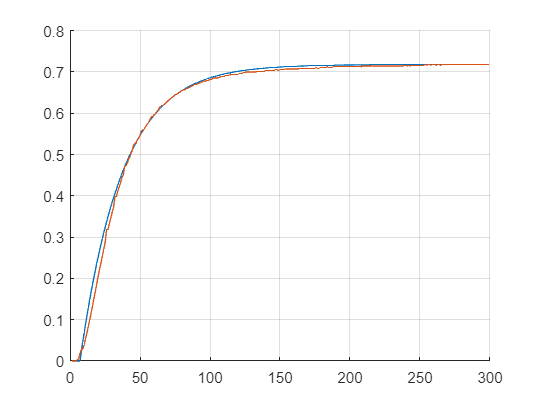

'compare' requires one of the following:
  System Identification Toolbox
  Model Predictive Control Toolbox
  Predictive Maintenance Toolbox

Error in Lab_3_Identyfikacja>id1rz (line 20)
compare()

y1=pomiary_3out(:,1) - pomiary_3out(1,1);
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
y3=pomiary_3out(:,3) - pomiary_3out(1,3);
t = 1:300;
k1=(y1(300,1)-y1(1,1))/1.0; T1 = 30; theta1 = 7;
k2=(y2(300,1)-y2(1,1))/1.0; T2 = 30; theta2 = 10;
k3=(y3(300,1)-y3(1,1))/1.0; T3 = 150; theta3 = 40;
id1rz(k1, T1, theta1, y1, t)

id1rz(k2, T2, theta2, y2, t)
id1rz(k3, T3, theta3, y3, t)

function [] = id1rz(k, T, theta, y, t)
obiektA21 = tf([0 k], [T 1], 'Inputdelay', theta)
[yA1, tA1] = step(obiektA21, t);
figure
hold on; grid on;
plot(tA1, yA1, t, y)
hold off;
compare()
end

function [] = id2rz(k, T1, T2, theta, y, t)
obiektA21 = tf([0 0 k], [T1*T2 T2+T1 1], 'Inputdelay', theta)
[yA1, tA1] = step(obiektA21, t);
figure
hold on; grid on;
plot(tA1, yA1, t, y)
hold off;
end